## Tarea 1

## Alejandro Brenes Calderon - C21319

## Santiago Fernández Sáenz - C22943 

**Pregunta 1**.  [**MATLAB**] 

El mayor cero de la ecuación $f(x) := x ^ {2} + bx + 1 = 0$ , con $b \in \mathbb{R}$, es: 


$$x_1 = \frac{-b + \sqrt{b^2 - 4}}{2}$$


**a)**

Para $b=1000$, se tiene la siguiente aproximación: 

x_1 = (-(1000) + sqrt(1000^2 -4))/(2)

x_1 = -0.0010

Así, para esta aproximación, se evalúa en $f\left(x\right)$: 

f_x1 = (x_1)^2 + (1000)*(x_1) + 1

f_x1 = -2.0621e-11

**b)** 

Ahora, para la aproximacioón de $x_1 \;$previamente obtendida, racionalizando el numerador se puede llegar a una expresión equivalente: 


$$\frac{-b+\sqrt{b^2 -4 }}{2} = \left(\frac{b - \sqrt{b^2 - 4}}{-2} \right) \left(\frac{b + \sqrt{b^2 -4}}{b + \sqrt{b^2 -4} } \right) = \frac{b^2 - b^2 + 4}{-2b - 2\sqrt{b^2 -4}} = \frac{4}{2(-b - \sqrt{b^2 - 4})} = \frac{2}{-b - \sqrt{b^2 - 4}}$$


Igualmente, se vuelve a aproximar $x$, tomando nuevamente $b=1000$: 

x_2 = (2)/(-(1000) - (1000^2 -4))

x_2 = -1.9980e-06

Ahora evaluamos en $f\left(x\right)$: 

f_x2 = (x_2)^2 + (1000)*(x_2) + 1

f_x2 = 0.9980

**c)**

El origen de la diferencia puede deberse a la complejidad de las operaciones y en el orden en que se realizan en cada caso. Ambos deben de realizar operaciones con numeros grandes, tales como ${1000}^2 -4$, sin embargo, el paso final difiere en que mientras una expresión simplemente divide entre dos, la cual es una operación sencilla, en la otra es más bien la expresión grande con las operaciones con los 1000s el denominador, por lo que esta operación es más compleja y podría distorsionar el resultado final. 

**Pregunta 2. **[**MATLAB**] Considere la función:

$$$f(x) = 816x^3 - 3835x^2 + 6000x - 3125$$$,

la cual tiene tres ceros racionales diferentes en el intervalo [1.4, 1.7].

Inicialmente, se genera la función correspondiente:

f = @(x) (816 * (x .^ 3)) - (3835 * (x .^ 2)) + (6000 * x) - 3125;

**a)** 

En este caso se inicia graficando el intervalo indicado, para tener una idea de las soluciones que existen

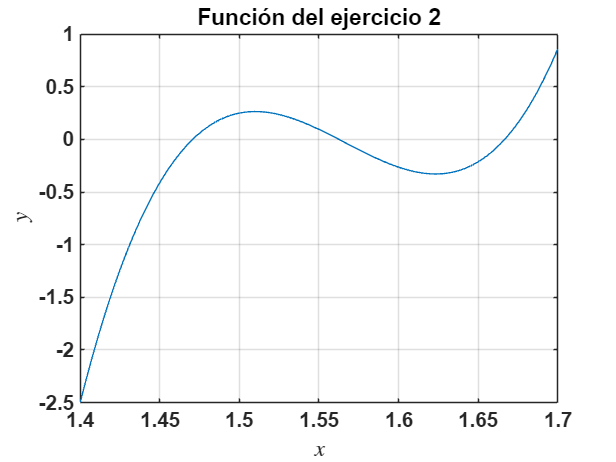

plot(linspace(1.4, 1.7), f(linspace(1.4, 1.7)))
grid on
title('Función del ejercicio 2')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
set(gca, 'FontName', 'Arial', 'FontSize', 14, 'FontWeight', 'Bold');

Después de algunas pruebas, se vió que la función `fzeros() `solo arroja un resultado cada vez que se usa, por lo cual, basándose en el gráfico, se reducirá el intervalo para que encuentre las 3 soluciones distintas.

fzero(f, [1.4 1.7])

ans = 1.6667

fzero(f, [1.5 1.6])

ans = 1.5625

fzero(f, [1.4 1.5])

ans = 1.4706

Se probaron distintos intervalos, en algunos casos, la función daba un error al poner puntos cuyas imágenes tenían el mismo signo, lo cual puede indicar que se utiliza el método de bisección en la función. Para comprobar esto, note que:

[x, fval, exitflag, output] = fzero(f, [1.4 1.7])

x = 1.6667

fval = 0

exitflag = 1

output = struct with fields:
    intervaliterations: 0
            iterations: 9
             funcCount: 11
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [1.4, 1.7]'


el parámetro *output* menciona que se usan los algoritmos de bisección e interpolación. Según lo explicado en clase, usualmente se combinan diversos métodos para hallar las raíces de una función, además, por el error que exige que las imágenes tengan distinto signo, se asume que inicialmente se utiliza el algoritmo de bisección y, posteriormente, el de interpolación.

**b)**

Para este caso iniciamos declarando algunas de las funciónes que ocupamos. Se inició buscando un poco de la sintaxis de la creación de funciónes en **MATLAB**, esto en la documentación oficial del programa (https://la.mathworks.com/help/matlab/ref/function.html).

Se encontraron algunos problemas al usar la función de Newton con vectores, por lo cual, estos se solucionaron aplicando la función `any `en la condición del while (https://la.mathworks.com/help/matlab/ref/any.html). Estos problemas se presentaban, probablemente, debido a que algunos valores iniciaban demasiado cerca del valor de convergencia, lo cual hace que la iteración se detenga rápidamente, pero esto entra en conflicto con los valores que no presentaban esa característica inicial, arrojando así valores erroneos.

% Derivada de f
fprima = @(x) (816 * 3 * (x .^ 2)) - (3835 * 2 * x) + 6000;

% Método para las iteraciones de Newton, basado en la función del método
% secante incluido en la plantilla de la tarea
function c = newton(fun, derivada, c0, epsilon)
    % Se calcula una iteración para iniciar la condición después
    c = c0 - (fun(c0) ./ derivada(c0));
    c1 = c0;

    % Se inicia la condición con los 2 valores correspondientes
    while any(abs(c - c1) > epsilon)
        c1 = c;
        c = c1 - (fun(c1) ./ derivada(c1));
    end
end

**c)**

Iniciamos con los valores iniciales que se requieren en el problema.

x0 = linspace(1.4,1.7);

Obtenemos los valores de convergencia con respecto a la función `f`.

valoresConv = newton(f, fprima, x0, (10 ^ -12));

Graficamos el resultado correspondiente.

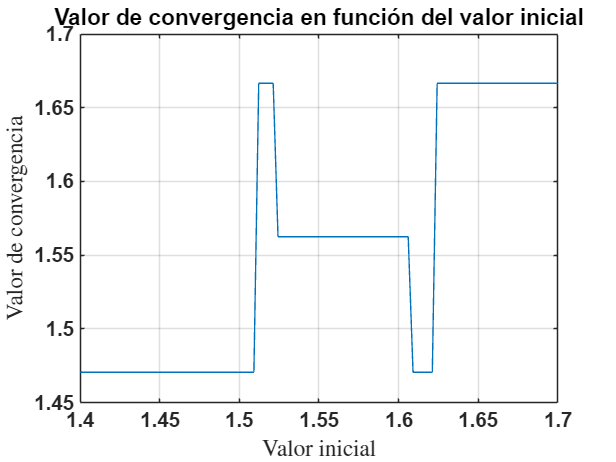

plot(x0, valoresConv)
grid on
title('Valor de convergencia en función del valor inicial')
xlabel('Valor inicial', 'Interpreter', 'latex')
ylabel('Valor de convergencia', 'Interpreter', 'latex')
set(gca, 'FontName', 'Arial', 'FontSize', 14, 'FontWeight', 'Bold');

**d)**

Para esta ocasión, ocupamos la segunda derivada de la función f, esta viene dada por:

fIIprima = @(x) 816 * 3 * 2 * x - 3835 * 2;

A continuación, se pretende graficar ambos lados de la desigualdad, esto para comparar visualmente si se cumple la cota para cada uno de los puntos.

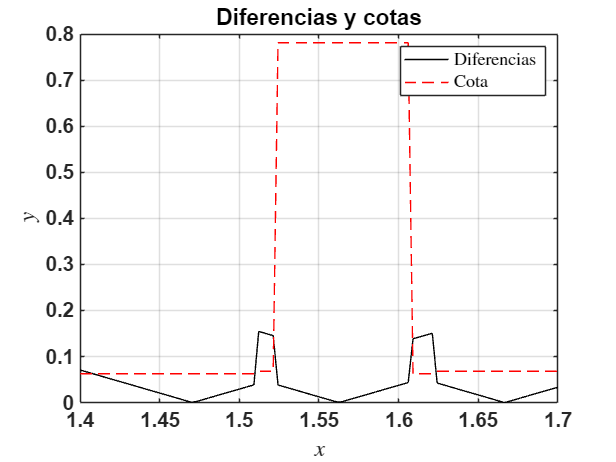

% Lado izquierdo de la desigualdad
valorC = abs(x0 - valoresConv);

% Lado derecho de la desigualdad
cota = (abs(fIIprima(valoresConv) ./ (2 * fprima(valoresConv)))) .^ -1;

% gráfico de comparación, basado en la plantilla de la tarea
figure;
plot(x0, valorC, 'k-', 'DisplayName', 'Diferencias');
hold on;

plot(x0, cota, 'r--', 'DisplayName', 'Cota');
grid on;

legend('show','Interpreter','Latex')

title('Diferencias y cotas');
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
set(gca,'FontName','Arial','FontSize',14,'FontWeight','Bold');

En este último gráfico se puede observar que la desigualdad no se cumple para todos los puntos, principalmente, en los intervalos antes y después de que la cota aumente, es decir, en esos intervalos se encuentran los estimados particularmente malos.

Note que los intervalos mencionados anteriormente coinciden en el comportamiento atípico del gráfico del valor de convergencia en función del valor inicial, pues, en este, uno esperaría un comportamiento de "escalera" hacia las raíces de la función, es decir, que al estar cerca de una de las soluciones, el algoritmo termine llegando a ella. Este comportamiento atípico puede deberse a que en esos intervalos no se cumple la desigualdad mencionada en el inciso:


$$|c_0 - c| \leq \left|\frac{f''(c)}{2 \cdot f'(c)} \right| ^ {-1}$$


lo cual queda claro en el último gráfico, por lo cual, esos intervalos no son parte de la base de atracción, eso hace que no haya garantía de que el algoritmo converja a un `c `que esté en el intervalo, dejando así, el comportamiento atípico en el gráfico de valores de convergencia según su valor inicial y la razón por la que estos son unos malos estimados.

**Pregunta 3. **La Ley de Enfriamiento de Newton dice que la razón de cambio de temperatura en el tiempo t de un objeto es proporcional a la diferencia entre la temperatura ambiente $T_a$ y la temperatura $T$ del objeto; i.e.,


$$\frac{dT}{dt} = k \cdot (T_a - T)$$


donde k es la constante de proporcionalidad.

**a)**

Iniciamos con la fórmula del inciso:


$$T(t) = T_a + (T_0 - T_a) \cdot e^{-kt}$$


Derivamos la misma:


$$\frac{\partial T}{\partial t} = (T_0 - T_a) \cdot e^{-kt} \cdot -k$$



$$\Longrightarrow \frac{\partial T}{\partial t} = -k \cdot (T_0 - T_a) \cdot e^{-kt}$$


Sumamos un cero:


$$\frac{\partial T}{\partial t} = -k \cdot (T_0 - T_a) \cdot e^{-kt} + k \cdot T_a - k \cdot T_a$$



$$\Longrightarrow \frac{\partial T}{\partial t} = k \cdot T_a - k \cdot (T_0 - T_a) \cdot e^{-kt} - k \cdot T_a$$



$$\Longrightarrow \frac{\partial T}{\partial t} = k \cdot T_a - k \left[(T_0 - T_a) \cdot e^{-kt} + T_a \right]$$


En este punto, note que $T = (T_0 - T_a) \cdot e^{-kt} + T_a$, por lo cual


$$\Longrightarrow \frac{\partial T}{\partial t} = k \cdot T_a - k \cdot T$$



$$\Longrightarrow \frac{\partial T}{\partial t} = k \cdot \left[T_a - T \right]$$


Lo cual es la fórmula de la ley de enfriamiento de Newton.

**b)**

Para encontrar el mínimo de este funciónal, iniciamos expandiendo la fórmula con los valores adecuados.


$$\sum_i \left(T(t_i) - T_i \right) ^ 2$$



$$\Longrightarrow \left(T(t_0) - T_0\right) ^ 2 + \cdots +  \left(T(t_4) - T_4\right) ^ 2$$



$$\Longrightarrow \left(T_a + (T_0 - T_a) \cdot e ^ {-k \cdot t_0} - T_0\right) ^ 2 + \cdots + \left(T_a + (T_0 - T_a) \cdot e ^ {-k \cdot t_4} - T_4\right) ^ 2$$



$$\Longrightarrow (16 \cdot e^{-k \cdot 0.2} - 15.72) ^ 2 + (16 \cdot exp^{-k \cdot 0.4} - 15.41) ^ 2 + (16 \cdot exp^{-k \cdot 0.6} - 15.12) ^ 2 + (16 \cdot exp^{-k \cdot 0.8} - 14.9) ^ 2$$


Usando las constantes que da el problema, se pondrá lo anterior como una función que depende de la variable k.

funcional_enf = @(k) (16 * exp(-k * 0.2) - 15.72) .^ 2 + (16 * exp(-k * 0.4) - 15.41) .^ 2 + (16 * exp(-k * 0.6) - 15.12) .^ 2 + (16 * exp(-k * 0.8) - 14.9) .^ 2;

Ahora, graficaremos la función para hacernos una idea de cómo es:

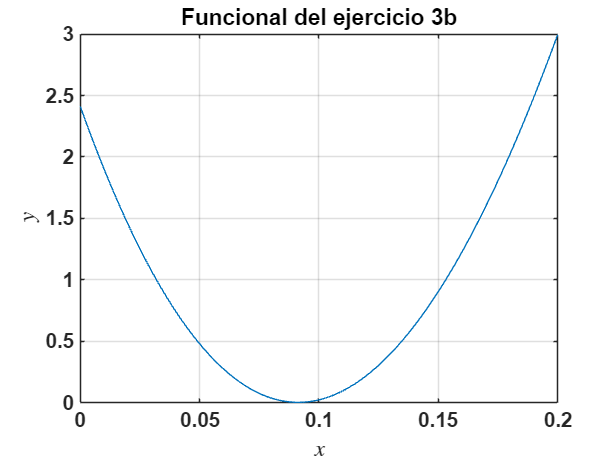

figure;
plot(linspace(0, 0.2), funcional_enf(linspace(0, 0.2)))
grid on
title('Funcional del ejercicio 3b')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
set(gca, 'FontName', 'Arial', 'FontSize', 14, 'FontWeight', 'Bold');

Con esto, encontramos el mínimo con el método secante, esto ya que converge con mayor velocidad que el de bisección, sin embargo, el grupo considera que obtener la derivada de esta función para usar el método de Newton es innecesario, debido a que su derivada puede tener muchos términos, por lo cual, se considera el método secante otorgado por el profesor en la plantilla de la tarea.

function c1 = secante(f,c0,c1)
    for k = 1:10000
        cnew = c1-f(c1)*(c1-c0)/(f(c1)-f(c0));
        c0 = c1;
        c1 = cnew;
    end
end

El mínimo del funciónal estaría dado por:

k = secante(funcional_enf, 0.05, 0.1)

k = 0.0915

Se comprueba que este es un mínimo, ya que:

funcional_enf(0.0915)

ans = 0.0018

El valor es aproximadamente 0.

**c)**

Ya que se pide el tiempo, iniciaremos despejando la ecuación correspondiente.


$$T = T_a + (T_0 - T_a) * e ^ {-k \cdot t}$$



$$\Longrightarrow T - T_a = (T_0 - T_a) * e ^ {-k \cdot t}$$



$$\Longrightarrow \frac{T - T_a}{T_0 - T_a} = e ^ {-k \cdot t}$$



$$\Longrightarrow ln \left(\frac{T - T_a}{T_0 - T_a} \right) = ln \left(e ^ {-k \cdot t} \right)$$



$$\Longrightarrow ln \left(\frac{T - T_a}{T_0 - T_a} \right) = -k \cdot t$$



$$\Longrightarrow \frac{ln \left(\frac{T - T_a}{T_0 - T_a} \right)}{-k} = t$$


Entonces, tomamos los valores del inciso:

$T_a = 31 \degree $, $T = 34\degree $, $T_0 = 37 \degree $

De forma que la persona falleció hace:

log(3 / 6) / -k

ans = 7.5761

horas.

**Pregunta 4. **

**a) **

Este metodo aprovecha las implicaciones y utilidades de la pendiente de una función y el signo en ciertas imágenes, ya que en función de estas dos herramientas se decide hacia dónde se debe de mover el intervalo. Así, hay cuatro posibilidades: 

i) Si ambas la pendiente y la imagen son positivas, la función está por encima del cero y a la derecha seguirá alejándose por el signo de la pendiente, por lo que hay que moverse a la izquierda con el intervalo. 

ii) Si la pendiente es positiva, pero la imagen negativa, la función esta por debajo del cero y a la derecha seguirá acercándose por el signo de la pendiente, por lo que hay que moverse a la derecha con el intervalo. 

iii) Si la pendiente es negativa, pero la imagen positiva, la función esta por encima del cero y a la derecha seguirá acercándose por el signo de la pendiente, por lo que hay que moverse a la derecha con el intervalo. 

iv) Y si ambas la pendiente y la imagen son negativas, pero la imagen positiva, la función esta por debajo del cero y a la derecha seguirá alejándose (cayendo) por el signo de la pendiente, por lo que hay que moverse a la izquierda con el intervalo. 

El proceso se detiene cuando ya sea, las imágenes de ambos extremos del intervalo tienen signo contrario, por lo que el cero se encuentra dentro; o las imágenes de los extremos izquierdos más recientes tengan signo contrario. 

En el gráfico siguiente se puede ver más a detalle el caso i), en rojo, y el caso ii), en verde: 

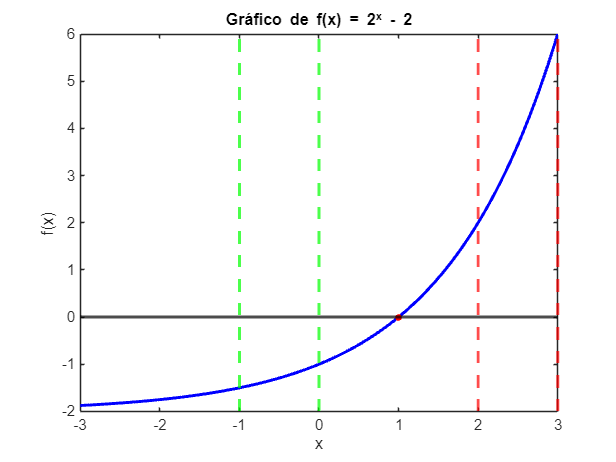

% Ejemplo: función creciente
f = @(x) 2.^x - 2;

x = linspace(-3, 3);

y = f(x);

figure; 
plot(x, y, '-b', 'LineWidth', 2); 

xlabel('x');
ylabel('f(x)');
title('Gráfico de f(x) = 2^x - 2');
hold on; 

% Cero de la función en (1,0)
scatter(1, 0, 20, 'r', 'filled'); 

%eje x
yline(0, '-k', 'LineWidth', 2); 

%primer intervalo
xline(2, '--r', 'LineWidth', 2); 
xline(3, '--r', 'LineWidth', 2); 

%segundo intervalo 
xline(-1, '--g', 'LineWidth', 2); 
xline(0, '--g', 'LineWidth', 2); 

Y en el gráfico siguiente se puede ver en cambio más a detalle más bien el caso iii), en amarillo, y el caso iv), en rosado: 

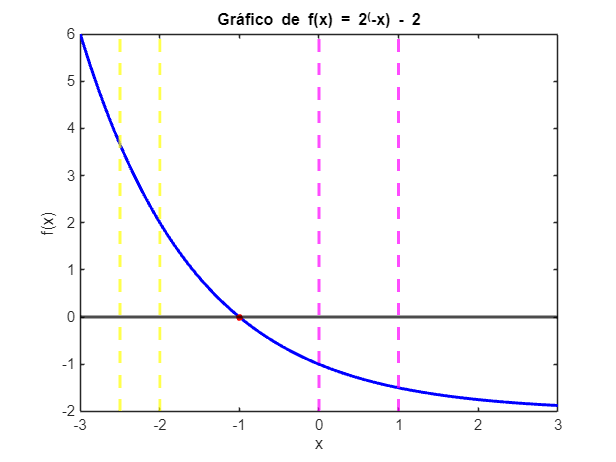

% Ejemplo: función decreciente
f = @(x) 2.^(-x) - 2;

x = linspace(-3, 3);

y = f(x);

figure; 
plot(x, y, '-b', 'LineWidth', 2); 

xlabel('x');
ylabel('f(x)');
title('Gráfico de f(x) = 2^(-x) - 2');
hold on; 

% Cero de la función en (-1,0)
scatter(-1, 0, 20, 'r', 'filled'); 

%eje x
yline(0, '-k', 'LineWidth', 2); 

%primer intervalo
xline(-2, '--y', 'LineWidth', 2); 
xline(-2.5, '--y', 'LineWidth', 2); 

%segundo intervalo 
xline(0, '--m', 'LineWidth', 2); 
xline(1, '--m', 'LineWidth', 2); 

**b) **

% Definimos la función f(x)
f = @(x) exp(x - 5) + x/3 - 2;

% Parámetros iniciales
a_k = 0; 
b_k = 1; 
s = 0.5;
ak_anterior = a_k;

%Ciclo for para el intervalo
for k = 1:10

    h = b_k - a_k + s;
    m_k = (f(b_k) - f(a_k)) / (b_k - a_k);

    if m_k > 0 && f(a_k) > 0
        a_k = a_k - h;
        b_k = a_k - s;
    elseif m_k > 0 && f(a_k) < 0
        a_k = b_k + s;
        b_k = b_k + h;
    elseif m_k < 0 && f(a_k) > 0
        a_k = b_k + s;
        b_k = b_k + h;
    else m_k < 0 && f(a_k) < 0
        a_k = a_k - h;
        b_k = a_k - s;
    end


    if f(a_k) * f(b_k) <= 0
        a = a_k;
        b = b_k;
        break;
    elseif k > 1 && f(a_k) * f(ak_anterior) <= 0
        a = min(a_k, ak_anterior);
        b = max(a_k, ak_anterior);
        break;
    end

    ak_anterior = a_k;
end

disp("Intervalo obtenido:")

Intervalo obtenido:


disp("[" + num2str(a) + ", " + num2str(b) + "]")

[3, 4.5]


Asi, el intervalo encontrado fue $\left\lbrack 3,4\ldotp 5\right\rbrack$

**c) **

Para esta seccion se necesitara la derivada de la función $f\left(x\right)=e^{\left(x-5\right)} +x/3-2$: 


$$f'(x) = e^{x-5}(x-5)\prime + \frac{1}{3} + 0= e^{x-5} + \frac{1}{3}$$


Ya que asi se puede aplicar el metodo de Newton, a saber: 


$$x_{k+1} = x_k - \frac{f(x_k)}{f'(x_k)}$$


Ademas, para el orden de convergencia, se tiene: 


$$\frac{|c_{k+1} - c|}{|c_k - c|^q} \approx \frac{|c_k - c|}{|c_{k-1} - c|^q}
\Longrightarrow \frac{|c_{k-1} - c|^q}{|c_k - c|^q} \approx \frac{|c_k - c|}{|c_{k+1} - c|} \Longrightarrow \left( \frac{|c_{k-1} - c|}{|c_k - c|} \right)^q \approx \frac{|c_k - c|}{|c_{k+1} - c|}$$



$$\Longrightarrow ln \left( \left( \frac{|c_{k-1} - c|}{|c_k - c|} \right)^q \right) \approx ln \left( \frac{|c_k - c|}{|c_{k+1} - c|} \right) \Longrightarrow q \cdot ln \left( \frac{|c_{k-1} - c|}{|c_k - c|} \right) \approx ln \left( \frac{|c_k - c|}{|c_{k+1} - c|} \right)

$$



$$\therefore q \approx \frac {ln \left( \frac{|c_k - c|}{|c_{k+1} - c|} \right)} {ln \left( \frac{|c_{k-1} - c|}{|c_k - c|} \right)}$$


Así, se procede con el código: 

% Definir la función f(x) y su derivada f'(x)
f = @(x) exp(x - 5) + x/3 - 2;
df = @(x) exp(x - 5) + 1/3;


c_exacto = 4.382357533223939;

x_k = 3.75; % Valor medio del intervalo encontrado
max_iter = 100;
tolerancia = 1e-6;

errores = zeros(max_iter, 1);
x_vals = zeros(max_iter, 1);
q_vals = zeros(max_iter-2, 1); 

% Método de Newton
for k = 1:max_iter
    f_xk = f(x_k);
    df_xk = df(x_k);
    
    x_k_siguiente = x_k - f_xk / df_xk;
    
    x_vals(k) = x_k_siguiente;
    errores(k) = abs(x_k_siguiente - c_exacto);
    
    if abs(x_k_siguiente - x_k) < tolerancia
        break;
    end
    
    if k >= 2
        q_vals(k-1) = log(abs(x_vals(k) - c_exacto) / abs(x_vals(k+1) - c_exacto)) / ...
                      log(abs(x_vals(k-1) - c_exacto) / abs(x_vals(k) - c_exacto));
    end
    
    x_k = x_k_siguiente;
end


disp(['Aproximación con Newton: ' num2str(x_k)]);

Aproximación con Newton: 4.3824


disp(['Error absoluto: ' num2str(errores(k))]);

Error absoluto: 1.3323e-14



disp('Orden de convergencia en cada iteración:');

Orden de convergencia en cada iteración:


disp(q_vals(1:k-2));

   -2.0924
   -2.0455
   -2.0226



**d)** 

Para este inciso, vamos a tomar un ejemplo que no es estrictamente monotona, la función ${f\left(x\right)=\;x}^3 +x^2$. Observe qué pasa si se escoge el intervalo $\left\lbrack \frac{-3-\sqrt{3}}{5},\frac{-3+\sqrt{3}}{5}\right\rbrack$

f = @(x) x.^3 + x.^2;

extr_izquierdo = f((-3-sqrt(3))/(5))

extr_izquierdo = 0.0480

extr_derecho = f((-3+sqrt(3))/(5))

extr_derecho = 0.0480

Ambos extremos son preimágenes de la misma imagen, esto porque en el extremo izquierdo, la pendiente de la función es positiva, y en el extremo derecho la pendiente de la función es negativa. En el siguiente gráfico se aprecia mejor: 

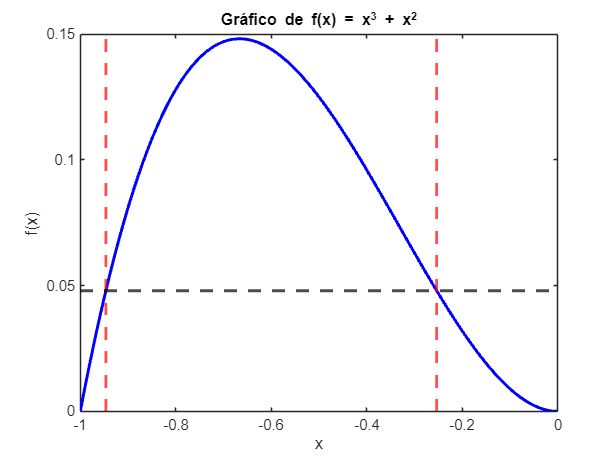

f = @(x) x.^(3) + x.^(2);

x = linspace(-1, 0);

y = f(x);

figure; 
plot(x, y, '-b', 'LineWidth', 2); 

xlabel('x');
ylabel('f(x)');
title('Gráfico de f(x) = x^3 + x^2');
hold on; 


xline((-3-sqrt(3))/(5), '--r', 'LineWidth', 2); 
xline((-3+sqrt(3))/(5), '--r', 'LineWidth', 2); 
yline(6/125, '--k', 'LineWidth', 2); 

Así, a la hora de calcular el m para el algoritmo, el resultado da 0, por lo que el algoritmo no puede determinar a cuál de los casos corresponde este escenario y no cumple con el propósito.

**Pregunta 5**

Dado n entero positivo, considere $\{(x_i, f(x_i))\}_{i = 0} ^ {n}$ nodos de interpolación dados, donde $a = x_0 < x_1 < \cdots < x_n = b$. Sabemos que el polinomio de interpolación de grado (a lo sumo n) se puede escribir en su forma de Lagrange.


$$p_n(x) = \sum_{k = 0} ^ {n} f(x_k) \cdot L_k(x) \hspace{5cm} (1)$$


En este ejercicio, estudiaremos otra manera diferente de calcular dicho polinomio. Es posible escribir:


$$p_n(x) = a_0 + a_1 \cdot (x - x_0) + a_2 \cdot (x - x_0) \cdot (x - x_1) + a_3 \cdot (x - x_0) \cdot (x - x_1) \cdot (x - x_2) + \cdots + a_n \cdot (x - x_0) \cdot (x - x_1) \cdots (x - x_{n - 1}) \hspace{0.5cm} (2)$$


**a)**

Con el polinomio (2), tome:


$$p_n(x_0) = a_0 \hspace{5cm} (a)$$


Ahora, del polinomio (1) se sabe que:


$$p_n(x_0) = \sum_{k = 0} ^ {0} f(x_k) \cdot L_k(x_0)$$



$$\Longrightarrow p_n(x_0) = f(x_0) \cdot L_0 (x_0)$$


Luego, por definición del polinomio, $L_0 (x_0) = 1$en este caso, entonces:


$$p_n(x_0) = f(x_0) \hspace{5cm} (b)$$


Igualando (a) y (b):


$$a_0 = f(x_0)$$


Este queda demostrado. Por otro lado, volviendo a (2) tenemos, con este último resultado:


$$p_n (x_1) = a_0 + a_1 \cdot (x_1 - x_0)$$



$$\Longrightarrow p_n (x_1) = f(x_0) + a_1 \cdot (x_1 - x_0) \hspace{5cm} (a')$$


Del polinomio (1) se observa que:


$$p_n(x_1) = \sum_{k = 0} ^ {1} f(x_k) \cdot L_k(x_1)$$



$$\Longrightarrow p_n(x_1) = f(x_0) \cdot L_0 (x_1) + f(x_1) \cdot L_1 (x_1)$$



$$\Longrightarrow p_n(x_1) = f(x_1) \hspace{5cm} (b')$$


Igualando (a') y (b'):


$$f(x_1) = f(x_0) + a_1 \cdot (x_1 - x_0)$$



$$\Longrightarrow f(x_1) - f(x_0) = a_1 \cdot (x_1 - x_0)$$



$$\Longrightarrow \frac{f(x_1) - f(x_0)}{(x_1 - x_0)} = a_1$$


**b)**

Similar al inciso anterior, tome (2), de forma que:


$$p_n (x_{2}) = f(x_0) + \frac{f(x_1) - f(x_0)}{x_1 - x_0} \cdot (x_2 - x_0) + a_2 \cdot (x_2 - x_0) \cdot (x_2 - x_1)$$


De (1) tenemos:


$$p_n (x_2) = f(x_2)$$


Igualando ambos:


$$f(x_2) = f(x_0) + \frac{f(x_1) - f(x_0)}{x_1 - x_0} \cdot (x_2 - x_0) + a_2 \cdot (x_2 - x_0) \cdot (x_2 - x_1)$$



$$\Longrightarrow f(x_2) - f(x_0) - f[x_0, x_1] \cdot (x_2 - x_0) = a_2 \cdot (x_2 - x_0) \cdot (x_2 - x_1)$$



$$\Longrightarrow \frac{f(x_2) - f(x_0) - f[x_0, x_1] \cdot (x_2 - x_0)}{(x_2 - x_0) \cdot (x_2 - x_1)} = a_2$$


**c)**

Con $n = 2$, el polinomio (2) sería:


$$p_2(x) = a_0 + a_1 \cdot (x - x_0) + a_2 \cdot (x - x_0) \cdot (x - x_1) \hspace{5cm} (*)$$


Del inciso `a) `sabemos:


$$a_0 = f(x_0) = f[x_0]$$



$$a_1 = \frac{f(x_1) - f(x_0)}{(x_1 - x_0)} = f[x_0, x_1]$$


Ahora, del inciso `b)` sabemos:


$$a_2 = \frac{f(x_2) - f(x_0) - f[x_0, x_1] \cdot (x_2 - x_0)}{(x_2 - x_0) \cdot (x_2 - x_1)}$$


Se procede a probar que lo anterior es igual a:


$$f[x_0, x_1, x_2] = \frac{f[x_1, x_2] - f[x_0, x_1]}{x_2 - x_0}$$


Note que:


$$\frac{f(x_2) - f(x_0) - f[x_0, x_1] \cdot (x_2 - x_0)}{(x_2 - x_0) \cdot (x_2 - x_1)} = \frac{\frac{f(x_2) - f(x_1)}{x_2 - x_1} - f[x_0, x_1]}{x_2 - x_1}$$



$$\Longrightarrow f(x_2) - f(x_0) - f[x_0, x_1] \cdot (x_2 - x_0) = f(x_2) - f(x_1) - f[x_0, x_1] \cdot (x_2 - x_1)$$



$$\Longrightarrow - f(x_0) - \frac{f(x_1) - f(x_0)}{x_1 - x_0} \cdot (x_2 - x_0) =- f(x_1) - \frac{f(x_1) - f(x_0)}{x_1 - x_0} \cdot (x_2 - x_1)$$



$$\Longrightarrow f(x_1) - f(x_0)= \frac{f(x_1) \cdot x_2 - f(x_0) \cdot x_2 - f(x_1) \cdot x_0 + f(x_0) \cdot x_0 - f(x_1) \cdot x_2 + f(x_0) \cdot x_2 + f(x_1) \cdot x_1 - f(x_0) \cdot x_1}{x_1 - x_0}$$



$$\Longrightarrow f(x_1) - f(x_0)= \frac{- f(x_1) \cdot x_0 + f(x_0) \cdot x_0 + f(x_1) \cdot x_1 - f(x_0) \cdot x_1}{x_1 - x_0}$$



$$\Longrightarrow \left(f(x_1) - f(x_0) \right) \cdot (x_1 - x_0) = - f(x_1) \cdot x_0 + f(x_0) \cdot x_0 + f(x_1) \cdot x_1 - f(x_0) \cdot x_1$$



$$\Longrightarrow f(x_1) \cdot x_1 - f(x_0) \cdot x_1 - f(x_1) \cdot x_0 + f(x_0) \cdot x_0 = - f(x_1) \cdot x_0 + f(x_0) \cdot x_0 + f(x_1) \cdot x_1 - f(x_0) \cdot x_1$$



$$\Longrightarrow f(x_1) \cdot x_1 - f(x_0) \cdot x_1 - f(x_1) \cdot x_0 + f(x_0) \cdot x_0 = f(x_1) \cdot x_1 - f(x_0) \cdot x_1 - f(x_1) \cdot x_0 + f(x_0) \cdot x_0$$


Se comprueba que ambas ecuaciones son iguales, es decir:


$$a_2 = f[x_0, x_1, x_2] = \frac{f[x_1, x_2] - f[x_0, x_1]}{x_2 - x_0}$$


Por lo cual, volviendo a (*) se concluye que, sustituyendo los valores conocidos:


$$p_2(x) = f[x_0] + f[x_0, x_1] \cdot (x - x_0) + f[x_0, x_1, x_2] \cdot (x - x_0) \cdot (x - x_1)$$


**d)**

De los incisos `a)`, `b)` y `c) `se tiene el caso base, es decir:


$$p_2(x) = f[x_0] + f[x_0, x_1] \cdot (x - x_0) + f[x_0, x_1, x_2] \cdot (x - x_0) \cdot (x - x_1)$$


Por lo cual, se tiene como hipótesis inductiva `(H.I)`:


$$p_{n-1}(x) = f[x_0] + f[x_0, x_1] \cdot (x - x_0) + f[x_0, x_1, x_2] \cdot (x - x_0) \cdot (x - x_1) + \cdots + f[x_0, x_1, \dots, x_{n - 1}] \cdot (x - x_0) \cdot (x - x_1) \cdots (x - x_{n - 2}) \hspace{0.25cm} (H.I)$$


Sabiendo esto, partimos de la hipótesis inductiva, de forma que sumamos a ambos lados:


$$f[x_0, x_1, \dots, x_{n}] \cdot (x - x_0) \cdot (x - x_1) \cdots (x - x_{n - 1})$$


De forma que tenemos:


$$p_{n - 1} (x) + f[x_0, x_1, \dots, x_{n}] \cdot (x - x_0) \cdot (x - x_1) \cdots (x - x_{n - 1}) $$



$$= f[x_0] + f[x_0, x_1] \cdot (x - x_0) + \cdots + f[x_0, x_1, \dots, x_{n}] \cdot (x - x_0) \cdot (x - x_1) \cdots (x - x_{n - 1})$$


Se probará que $p_{n} (x) = p_{n - 1} (x) + f[x_0, x_1, \dots, x_{n}] \cdot (x - x_0) \cdot (x - x_1) \cdots (x - x_{n - 1}) $. Primero note que si $x = x_i, \forall i \in \{0, 1, \dots, n-1 \}$, el polinomio equivale a la i-ésima imagen, pues:


$$p_{n - 1} (x) + f[x_0, x_1, \dots, x_{n}] \cdot (x - x_0) \cdots (x - x_i) \cdots (x - x_{n - 1}) $$



$$= f[x_0] + f[x_0, x_1] \cdot (x - x_0) + \cdots + f[x_0, x_1, \dots, x_{i + 1}] \cdot (x - x_0) \cdot (x - x_1) \cdots (x - x_{i}) + \cdots \hspace{2cm} (A)$$


Ya que si $x = x_i$, tenemos:


$$x - x_i = 0$$


Volviendo a `(A)`:


$$p_{n-1} (x) = f[x_0] + f[x_0, x_1] \cdot (x - x_0) + \cdots + f[x_0, x_1, \dots, x_{i}] \cdot (x - x_0) \cdot (x - x_1) \cdots (x - x_{i - 1})$$


Y por (1):


$$p_{n - 1} (x_i) = f(x_i) \hspace{12.35cm} \forall i \in \{0, 1, \dots, n-1\}$$


Con eso, se prueba que hasta la i-ésima imagen, se sigue cumpliendo que $p_n (x_i) = f(x_i)$, ya que según las últimas 2 igualdades:


$$f(x_i) = f[x_0] + f[x_0, x_1] \cdot (x - x_0) + \cdots + f[x_0, x_1, \dots, x_{i}] \cdot (x - x_0) \cdot (x - x_1) \cdots (x - x_{i - 1}) \hspace{2cm} \forall i \in \{0, 1, \dots, n-1\}$$


Ahora, note que del polinomio:


$$f(x_n) = f[x_0] + f[x_0, x_1] \cdot (x_n - x_0) + \cdots + f[x_0, x_1, \dots, x_{n}] \cdot (x_n - x_0) \cdot (x_n - x_1) \cdots (x_n - x_{n - 1})$$



$$\Longrightarrow f(x_n) - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots = f[x_0, x_1, \dots, x_{n}] \cdot (x_n - x_0) \cdot (x_n - x_1) \cdots (x_n - x_{n - 1})$$



$$\Longrightarrow f[x_0, x_1, \dots, x_{n}] = \frac{f(x_n) - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots - f[x_0, x_1, \dots, x_{n - 1}] \cdot (x_n - x_0) \cdots (x_n - x_{n - 2})}{(x_n - x_0) \cdot (x_n - x_1) \cdots (x_n - x_{n - 1})}$$



$$\Longrightarrow \frac{f[x_1,\ldots,x_n]- f[x_0,x_1,\ldots,x_{n-1}]}{x_n-x_0} = \frac{f(x_n) - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots - f[x_0, x_1, \dots, x_{n - 1}] \cdot (x_n - x_0) \cdots (x_n - x_{n - 2})}{(x_n - x_0) \cdot (x_n - x_1) \cdots (x_n - x_{n - 1})}$$



$$\Longrightarrow f[x_1,\ldots,x_n]- f[x_0,x_1,\ldots,x_{n-1}] = \frac{f(x_n) - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots - f[x_0, x_1, \dots, x_{n - 1}] \cdot (x_n - x_0) \cdots (x_n - x_{n - 2})}{ (x_n - x_1) \cdots (x_n - x_{n - 1})}$$



$$\Longrightarrow f[x_1,\ldots,x_n]$$



$$= \frac{f(x_n) - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots - f[x_0, x_1, \dots, x_{n - 1}] \cdot (x_n - x_0) \cdots (x_n - x_{n - 2})}{(x_n - x_1) \cdots (x_n - x_{n - 1})}$$



$$+ \frac{f[x_0,x_1,\ldots,x_{n-1}] \cdot (x_n - x_1) \cdots (x_n - x_{n - 1})}{(x_n - x_1) \cdots (x_n - x_{n - 1})}$$



$$\Longrightarrow \frac{f[x_2,\ldots,x_n]- f[x_1,x_2,\ldots,x_{n-1}]}{x_n-x_1} $$



$$= \frac{f(x_n) - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots - f[x_0, x_1, \dots, x_{n - 1}] \cdot (x_n - x_0) \cdots (x_n - x_{n - 2})}{(x_n - x_1) \cdots (x_n - x_{n - 1})}$$



$$+ \frac{f[x_0,x_1,\ldots,x_{n-1}] \cdot (x_n - x_1) \cdots (x_n - x_{n - 1})}{(x_n - x_1) \cdots (x_n - x_{n - 1})}$$



$$\Longrightarrow f[x_2,\ldots,x_n]$$



$$= \frac{f(x_n) - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots - f[x_0, x_1, \dots, x_{n - 1}] \cdot (x_n - x_0) \cdots (x_n - x_{n - 2})}{(x_n - x_2) \cdots (x_n - x_{n - 1})}$$



$$+ \frac{f[x_0,x_1,\ldots,x_{n-1}] \cdot (x_n - x_1) \cdots (x_n - x_{n - 1}) + f[x_1,x_2,\ldots,x_{n-1}] \cdot (x_n - x_2) \cdots (x_n - x_{n - 1})}{(x_n - x_2) \cdots (x_n - x_{n - 1})}$$


Después de repetir el proceso anterior múltiples veces, llegamos a:


$$\Longrightarrow f[x_{n - 1},x_n]$$



$$= \frac{f(x_n) - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots - f[x_0, x_1, \dots, x_{n - 1}] \cdot (x_n - x_0) \cdots (x_n - x_{n - 2})}{(x_n - x_{n - 1})}$$



$$+ \frac{f[x_0,x_1,\ldots,x_{n-1}] \cdot (x_n - x_1) \cdots (x_n - x_{n - 1}) + \cdots + f[x_{n - 2}, x_{n-1}] \cdot (x_{n} - x_{n - 1})}{(x_{n} - x_{n - 1})}$$



$$\Longrightarrow \frac{f(x_{n}) - f(x_{n - 1})}{x_n - x_{n - 1}}$$



$$= \frac{f(x_n) - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots - f[x_0, x_1, \dots, x_{n - 1}] \cdot (x_n - x_0) \cdots (x_n - x_{n - 2})}{(x_n - x_{n - 1})}$$



$$+ \frac{f[x_0,x_1,\ldots,x_{n-1}] \cdot (x_n - x_1) \cdots (x_n - x_{n - 1}) + \cdots + f[x_{n - 2}, x_{n-1}] \cdot (x_{n} - x_{n - 1})}{(x_{n} - x_{n - 1})}$$



$$\Longrightarrow f(x_{n}) - f(x_{n - 1})$$



$$= f(x_n) - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots - f[x_0, x_1, \dots, x_{n - 1}] \cdot (x_n - x_0) \cdots (x_n - x_{n - 2})}$$



$$+ f[x_0,x_1,\ldots,x_{n-1}] \cdot (x_n - x_1) \cdots (x_n - x_{n - 1}) + \cdots + f[x_{n - 2}, x_{n-1}] \cdot (x_{n} - x_{n - 1})}$$



$$\Longrightarrow - f(x_{n - 1})$$



$$= - f[x_0] - f[x_0, x_1] \cdot (x_n - x_0) - \cdots - f[x_0, x_1, \dots, x_{n - 1}] \cdot (x_n - x_0) \cdots (x_n - x_{n - 2})}$$



$$+ f[x_0,x_1,\ldots,x_{n-1}] \cdot (x_n - x_1) \cdots (x_n - x_{n - 1}) + \cdots + f[x_{n - 2}, x_{n-1}] \cdot (x_{n} - x_{n - 1})}$$


Simplificando, se comprueba el resultado.

**e) **

Si los valores $x_0$ y $x_1$estan a una muy corta distancia, al hacer la resta se vuelve un valor muy pequeño, el cual, si se reduce lo suficiente, podria llegar a alterar la fraccion $\frac{f\left(x_1 \right)-f\left(x_0 \right)}{x_1 -x_0 }$ llegando a una forma indefinida, generando una posible mala aproximación de la derivada o de la interpolación.

**f)**

Se definen, en primer lugar, los puntos para realizar los cálculos: 


$$(x_0, f(x_0)) = (1,-2), (x_1, f(x_1)) = (2,2), (x_2, f(x_2)) = (3,14), (x_3, f(x_3)) = (4,40) $$


Ahora las diferencias divididas: 


$$f[x_0. x_1] = \frac{f(x_1) - f(x_0)}{x_1 - x_0} = \frac{2-(-2)}{2-1} = 4$$



$$f[x_1,x_2] = \frac{f(x_2) - f(x_1)}{x_2=x_1} = \frac{14-2}{3-2} = 12$$



$$f[x_2, x_3] = \frac{f(x_3) - f(x_2)}{x_3 - x_2} = \frac{40-14}{4-3} = 26$$



$$\Longrightarrow f[x_0, x_1, x_2] = \frac{12-4}{3-1} = 4 \land f[x_1, x_2, x_3] = \frac{26-12}{4-2} = 7$$



$$\therefore f[x_0, x_1, x_2, x_3] = \frac{7-4}{4-1} = 1$$


Y asi, el polinomio interpolante de Lagrange es: 


$$p_3(x) = -2 + 4(x-1) + 4(x-1)(x-2) + 1(x-1)(x-2)(x-3)$$


**g)**

En primer lugar, siguiendo la sugerencia, defina el residuo:


$$R(x)  := f(x) - p_n (x)$$


Se sabe de (1) que:


$$p_n (x_i) = f(x_i) \hspace{12.75cm} \forall i \in \{0, 1, \dots, n - 1\}$$


Por lo cual:


$$R(x_i) = 0 \hspace{13.35cm} \forall i \in \{0, 1, \dots, n - 1\}$$


Inicialmente, tomamos los puntos $x_0$ y $x_1$, por lo anterior, sabemos que:


$$R(x_0) = R(x_1) = 0$$


Esto nos permite utilizar el teorema de Rolle para $x_0$ y $x_1$, de manera que podemos afirmar que existe, al menos, un cero en la derivada de la función entre esos 2 puntos.

De forma similar, seguimos con los puntos $x_1$ y $x_2$, nuevamente, en el residuo, las imágenes en estos puntos son 0:


$$R(x_1) = R(x_2) = 0$$


Por lo cual, nuevamente, usamos el teorema de Rolle, de forma que existe, al menos, un cero en la derivada de la función entre esos 2 puntos.

Repetimos este proceso para cada uno de los puntos restantes, simplemente seleccionamos 2 de los puntos con subíndice consecutivo ($x_i, x_{i+1}, \forall i \in \{0, 1, \dots, n-2\}$), de forma que sabemos que la derivada tiene, como mínimo, (n - 1) puntos en donde se hace 0.

Una vez con esto, tomamos la derivada de f ($f'$) como una nueva función g, de forma que sabemos que la función g tiene, por lo menos, (n - 1) puntos en donde su imagen es 0, llamaremos $w_i
$ a los puntos en donde se cumple esto, es decir:


$$g(w_i) = 0 \hspace{13.25cm} \forall i \in \{0, \dots, n - 2\}$$


Luego, tomamos 2 puntos, inicialmente $w_0$ y $w_1$, de forma que se cumple:


$$g(w_0) = g(w_1) = 0$$


Esto nos permite usar teorema de Rolle una vez más, lo cual garantiza que hay, como mínimo, 1 punto en el intervalo $[w_0, w_1]$ en donde la derivada de g se vuelve 0.

Este proceso se repite nuevamente con todos los puntos w consecutivos ($w_i, w_{i+1}, \forall i \in \{0, 1, \dots, n-3\}$), es decir, al final tendremos, usando el teorema de Rolle en cada par de puntos consecutivos, al menos, un total de (n - 2) puntos en donde la derivada de g se vuelve 0.

Este proceso de tomar los puntos consecutivos en donde la función se hace 0, usar teorema de Rolle para encontrar los ceros de la derivada y, posteriormente, tomar la derivada como una nueva función, para repetir este proceso se hace hasta la derivada (n-1) del residuo.

Con el proceso explicado anteriormente, es claro que en esa derivada hay 2 puntos en los que la función se hace 0, los llamaremos $z$, de forma que:


$$R ^ {(n - 1)} (z_0) = R ^ {(n - 1)} (z_1) = 0$$


Usando teorema de Rolle una vez más, tenemos que la n-ésima derivada se hace 0 en un punto. Siguiendo la fórmula del inciso, se puede ver que este punto en donde la última derivada obtenida se hace 0 es el $\xi$ que buscamos.

**h) **

Para el caso de $n=1$, se tiene: 


$$f[x_0, x_1] = \frac{f(x_1) - f(x_0)}{x_1 - x_0} = \frac{f \prime (\xi)}{1!} = f \prime (\xi)$$


Es decir, similar al Teorema del Valor Medio, dentro del intervalo $\left\lbrack a,b\right\rbrack$ existe un valor para el cual la pendiente entre los dos puntos que se usan es igual a la derivada en ese valor.

**i)**

Se buscó sobre la función length (https://la.mathworks.com/help/matlab/ref/length.html). La función es la siguiente:

function pol = polin_lag(nodos, x, fun)
    % Definimos las variables que ocuparemos a lo largo del problema
    num_nodos = length(nodos) + 1;
    pol = 0;

    % Se hace una lista que irá redefiniendo sus valores de f[x0, x1, ...]
    lista_val = nodos;

    % Los productos se definen en un vector
    productos = x - nodos;
    
    % Se agrega un elemento a los productos, para ir multiplicando desde la
    % primera iteración
    productos = [1 productos];
    
    % Se procede a obtener iterativamente el valor del polinomio
    for i = 1:(num_nodos - 1)
        % Se agrega el valor correspondiente al polinomio
        pol = pol + lista_val(1) * prod(productos(1:i));
        
        % Se hace la lista para la siguiente iteración
        lista_val = ((fun(lista_val(2:end)) - fun(lista_val(1:(end - 1)))) ./ ((lista_val(2:end) - lista_val(1:(end - 1)))));
    end
end

**j)**

En primer lugar, la función coorrespondiente viene dada por:

fun_aprox = @(x) 1 ./ (1 + 25 * x .^ 2);

Antes de los valores del polinomio, obtendremos los valores de los nodos correspondientes:

nodos_cheb = cos((((0:9) * pi) ./ (10)));
nodos_equid = -1 + (0:9) * (2 / 10);

Calculamos los polinomios correspondientes.

% Eje x
xx = linspace(-1,1,1e3);

% Iniciamos los vectores de ceros, pues la ecuación no está vectorizada
pol_equid = zeros(1, length(xx));
pol_cheb = zeros(1, length(xx));

% Llenamos los valores
for i = 1:length(xx)
    pol_equid(i) = polin_lag(nodos_equid, xx(i), fun_aprox);
    pol_cheb(i) = polin_lag(nodos_equid, xx(i), fun_aprox);
end

Ahora graficamos todas las curvas.

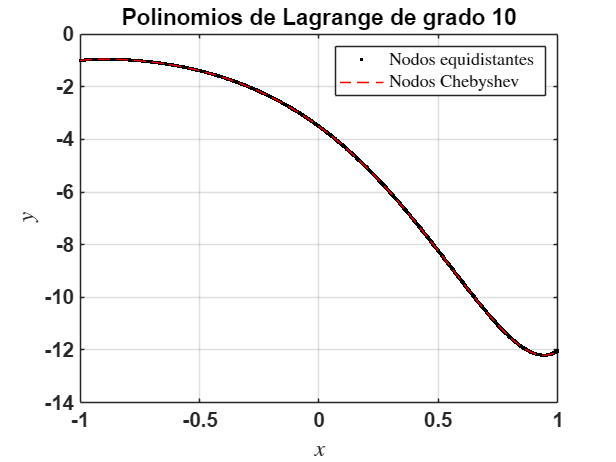

figure;
plot(xx, pol_equid, 'k.', 'DisplayName', 'Nodos equidistantes');
hold on;

plot(xx, pol_cheb, 'r--', 'DisplayName', 'Nodos Chebyshev');
grid on;

legend('show','Interpreter','Latex')

title('Polinomios de Lagrange de grado 10');
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
set(gca,'FontName','Arial','FontSize',14,'FontWeight','Bold');